# Homework 7

## Problem 14.42

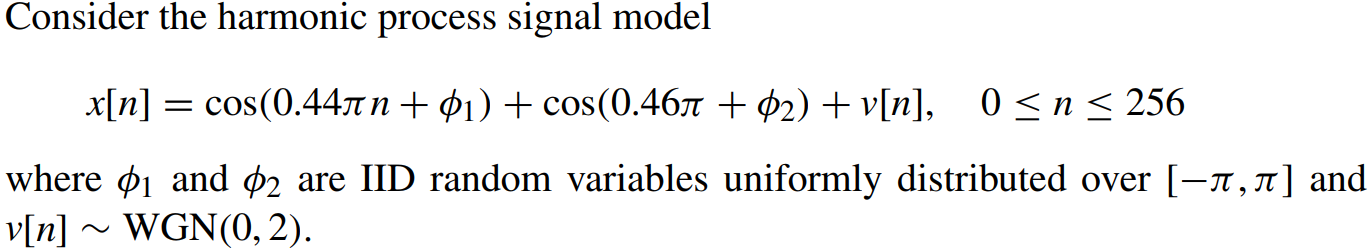

The autocorrelation of real sinusoid $z\left(n\right)=A\;\cos \left(\omega_0 n+\phi \right)$ is $r_{\mathrm{zz}} \left(\ell \right)=\frac{A^2 }{2}\cos \left(\omega_0 \ell \right)$. 

Since the PSD is the Fourier transform of the autocorrelation, we get:

        
$$S_{\mathrm{zz}} \left(\omega \right)=\frac{A^2 }{4}\delta \left(\omega +\omega_0 \right)+\frac{A^2 }{4}\delta \left(\omega -\omega_0 \right)$$


This means that power is concentrated at $\pm \omega_0$. In the PSD, we will therefore see two peaks ${\pm \omega }_0$ 

The autocorrelation of white Gaussian noise is $r_{\mathrm{vv}} \left(\ell \right)=\sigma_v^2 \delta \left(\ell \right)=2\delta \left(\ell \right)$. The PSD of Gaussian noise is constant around $\sigma_v^2$.

So the true PSD should be something like:


$$S_{\mathrm{xx}} \left(\omega \right)=\frac{1}{4}\delta \left(\omega -0\ldotp 44\pi \right)+\frac{1}{4}\delta \left(\omega -0\ldotp 46\pi \right)+2$$


### 1) Estimate the PSD using the periodogram and plot the spectrum.

N = 256;
n = 0:N-1;
v = randn(1,N) * sqrt(2);
phi = 2*pi*(rand(1,2)-0.5);
x = cos(0.44*pi*n + phi(1)) + cos(0.46*pi*n + phi(2)) + v;

%plot(n, x); xlim([0, N]);

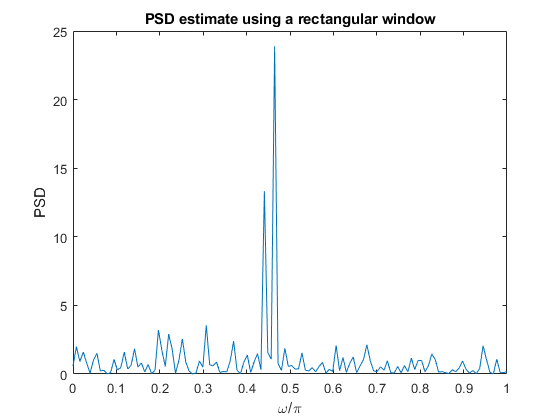

I = periodogram(x);
w = linspace(0,1,N/2)*pi;
IdB = db(I(1:N/2));
plot(w/pi, I(1:N/2));
xlabel('\omega/\pi')
ylabel('PSD')
title('PSD estimate using a rectangular window')

### 2) Estimate the PSD using the modified periodogram with Bartlett window  

Estimate the PSD using the modified periodogram with Bartlett window and plot the spectrum.  

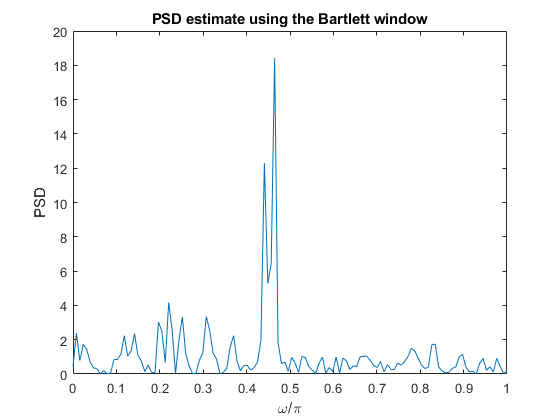

L = N;
I = periodogram(x, bartlett(L));
w = linspace(0,1,N/2)*pi;
IdB = db(I(1:N/2));
plot(w/pi, I(1:N/2));
xlabel('\omega/\pi')
ylabel('PSD')
title('PSD estimate using the Bartlett window')

### 3) Estimate the PSD using the Blackman–Tukey method

Estimate the PSD using the Blackman–Tukey method with Parzen window and *L*=32 and plot the spectrum.

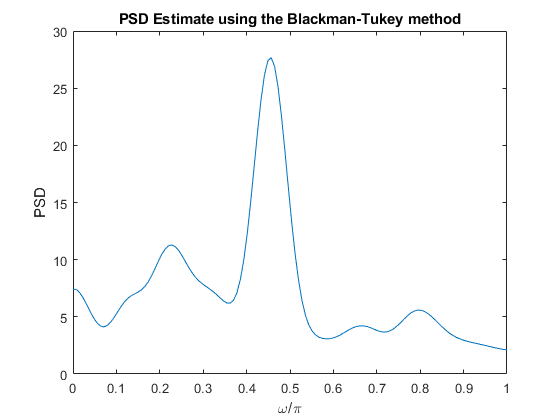

L = 32;
K = N;
I = psdbt(x,L,K);
plot(w/pi, I(1:N/2));
xlabel('\omega/\pi')
ylabel('PSD')
title('PSD Estimate using the Blackman-Tukey method')

### 4) Which method performs best in terms of signal resolution?

## Problem 14.57

This problem uses the signal file f16.mat that contains noise recorded at the copilot’s seat of an F-16 airplane using a 16 bit A/D converter with $F_S =19\ldotp 98$ kHz. 

  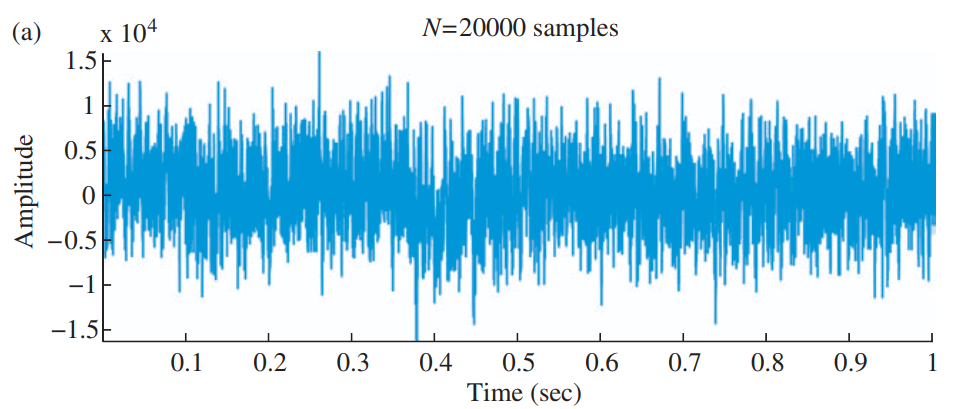

Figure (a) shows a waveform of F-16 noise recorded at the co-pilot’s seat with a sampling rate of 19.98 kHz using a 16 bit ADC.  

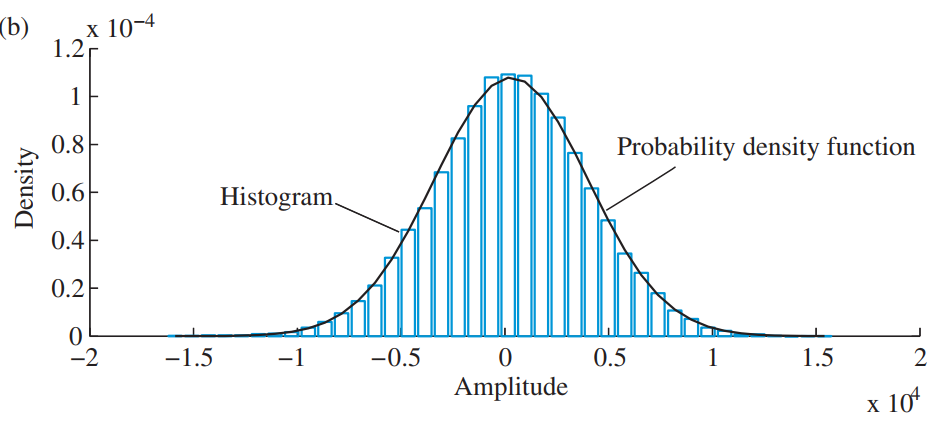

Figure (b) shows the histogram and theoretical probability density function of the F-16 noise.

We want to analyze this signal in terms of its ACRS and its spectral characteristics.  

### 1) Compute and plot the ACRS estimate of the noise process.

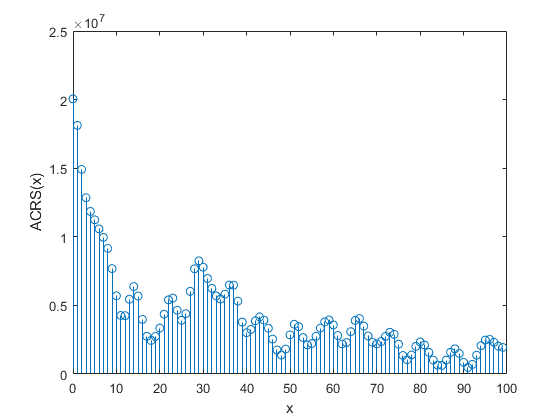

load('f16.mat')
x = f16;
L = 100;
r_xx = acrsfft(x, L);
stem(0:L-1, r_xx)
xlabel('x')
ylabel('ACRS(x)')

### 2) Estimate model parameters for an *AR**(2) and AR(4) *models.

### 3) Compute and plot the PSD estimate using the AR(2) and AR(4) models.  

### 4) Compute and plot the periodogram PSD estimate of the noise process.  

### 5) Compute the Bartlett PSD estimate

Compute the Bartlett PSD estimate using L = 32, 64, and 128. Plot your result of the averaged estimate.

### 6) Compute the Blackman–Tukey PSD estimate

Compute the Blackman-Tukey PSD estimate using *L *= 32, 64, and 128 using the Bartlett lag window. Plot your result of the averaged estimate.

### 7) Compute the Welch PSD estimate

Compute the Welch PSD estimate using 50% overlap, Hamming window, and *L *= 32, 64, and 128. Plot your result of the averaged estimate.  

### 8) Compare the plots in the above four parts and comment on your observation.  

## ADSI Problem 4.21: Minimum variance spectral estimation

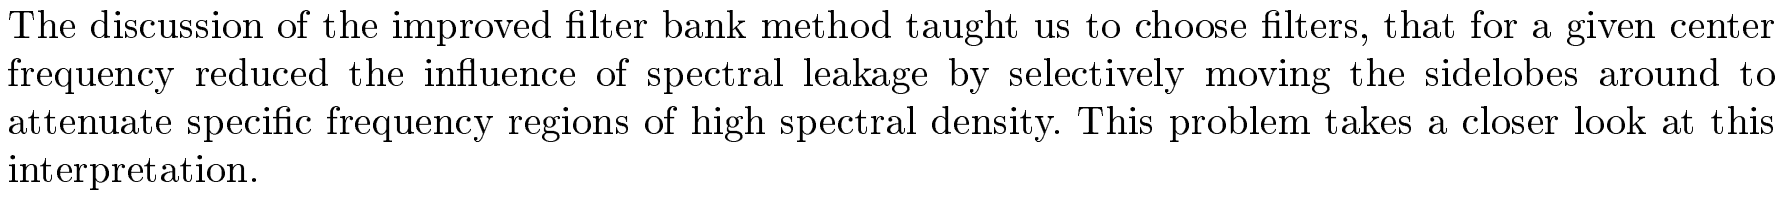

### 1) Create a stable signal model

### 2) Use the signal model to plot the true spectrum.  

### 3) Create a realization of the signal and determine the autocorrelation matrix ***R****x *in an appropriate size.

### 4) Calculate the spectrum using Eq. (14.4.12) from the note.

        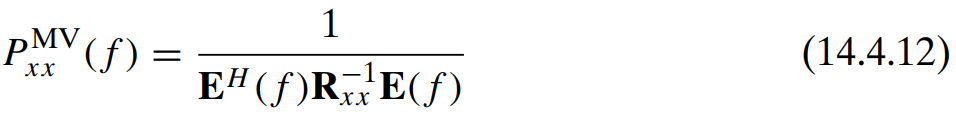

### 5) Calculate the optimum filters

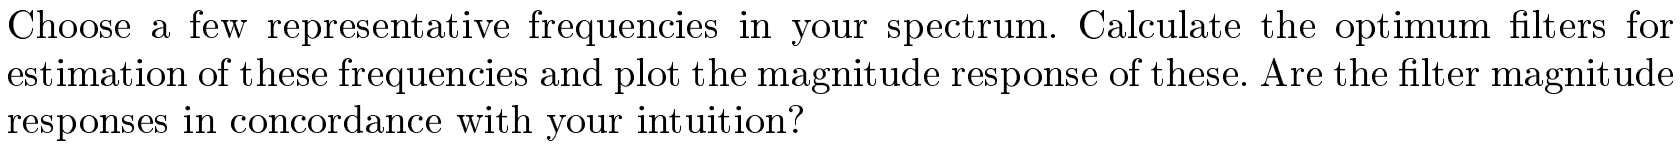

## ADSI Problem 4.22: Minimum variance and spectral resolution  

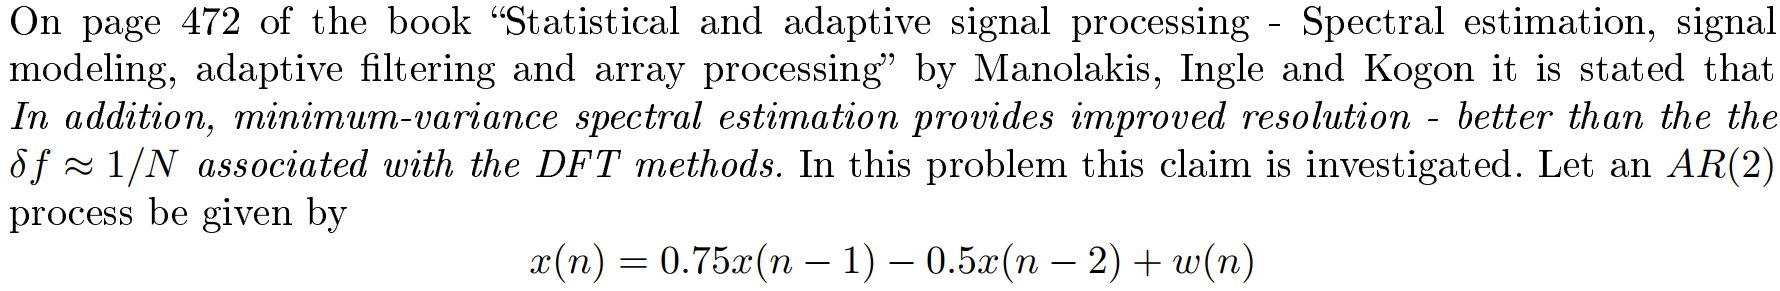

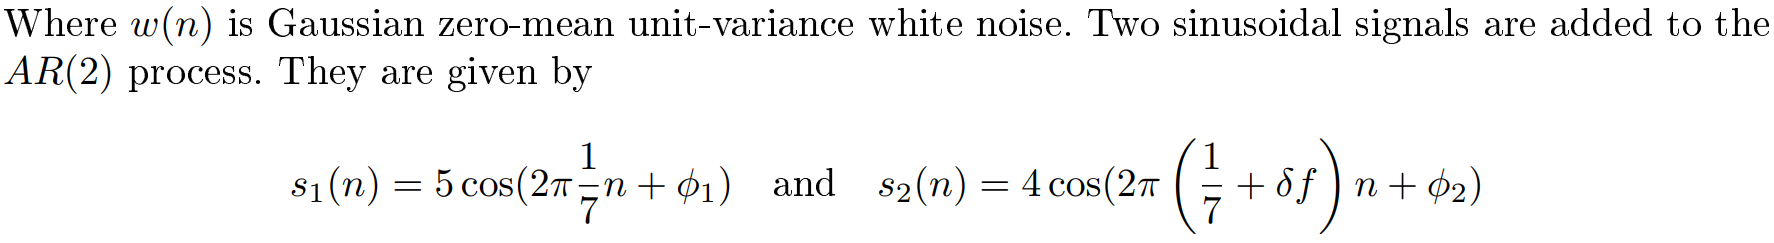

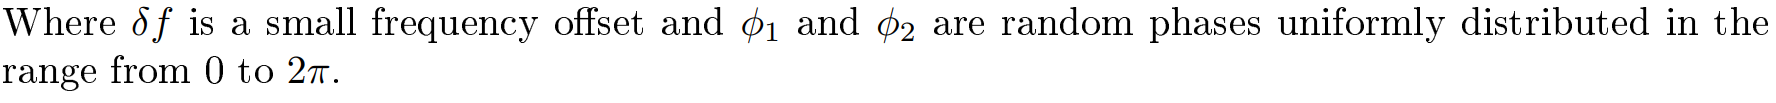

### 1) Create a realisation of the signal

### 2) Plot the spectrum of the process using minimum variance and the periodogram

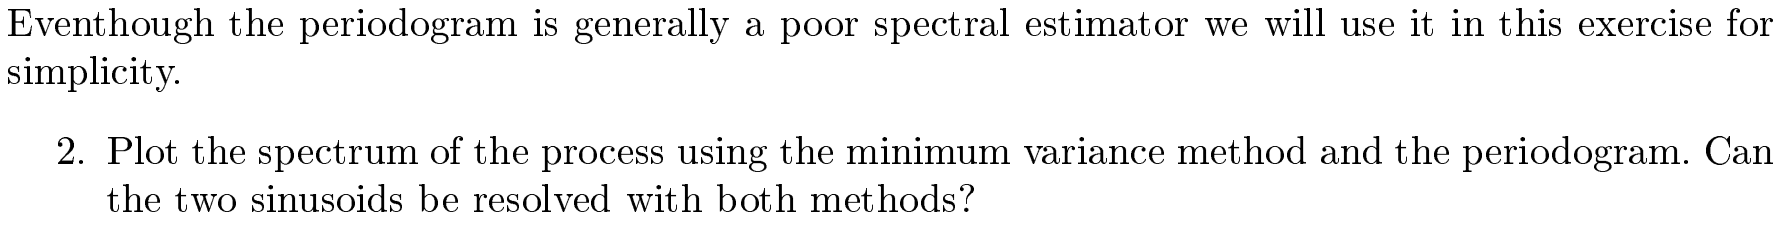

### 3) Verify if the book's claim is justified

## Problem 2 from Exam 2012: Construct an AR(2) model using a signal from a random process

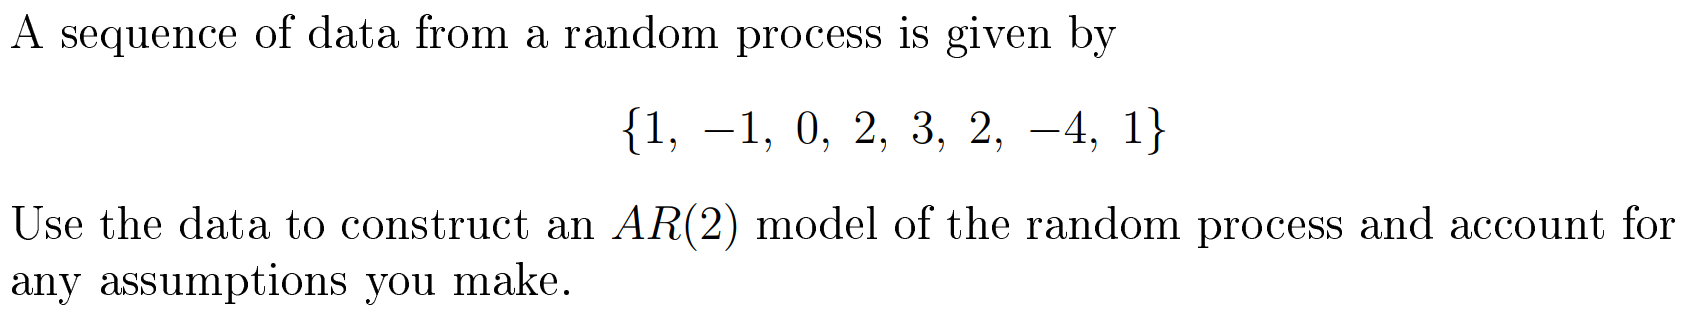

## Functions

function r=acrs(x, L)
    % Computes the ACRS r[m] for 0<= m <= L
    % r=acrs(x-mean(x),L) yields the ACVS
    N=length(x);
    x1=zeros(N+L-1,1);
    x2=x1;
    x1(1:N,1)=x;
    for m=1:L
        x2=zeros(N+L-1,1);
        x2(m:N+m-1,1)=x;
        r(m)=x1'*x2;
    end
    r=r(:)/N;
end

function I=psdper(x, K)
    % Compute periodogram I(ω) using the FFT.
    % K-point FFT >= N
    N=length(x);
    X=fft(x,K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function r=acrsfft(x, L)
    % Computate the autocorrelation sequence using the FFT.
    % r=acrsfft(x-mean(x),L) yields the ACVS
    N=length(x);
    Q=nextpow2(N+L);
    X=fft(x,2^Q);
    r0=real(ifft(X.*conj(X)));
    r=r0(1:L)/N;
end

function I=psdmodper(x, K)
    % Compute the modified periodogram PSD estimate.
    % K-point FFT >= N
    N=length(x);
    w=hann(N); % choose window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    X=fft(x(:).*w(:),K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function S=psdbt(x, L, K)
    % Computate the Blackman–Tukey PSD estimate.
    % Blackman–Tukey PSD estimator of S(2*pi*k/K)
    if size(x,1) < size(x,2)
        x = x';
    end
    N=length(x);
    w=hann(N); % Data window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    x=x.*w; % Data windowing
    r=acrsfft(x,L);
    wc=parzenwin(2*L-1); % Lag window
    rw=r.*wc(L:2*L-1); % Lag windowing
    g=zeros(K,1);
    g(1:L)=rw;
    g(K-L+2:K)=flipud(rw(2:L));
    G=fft(g,K); % f even => F real
    S=2*real(G(1:K/2)); 
    S(1)=S(2);
end

function S=psdwelch(x, L, K)
    % Compute the Welch PSD estimate.
    % Welch PSD estimator of S(2*pi*k/K)
    M=fix((length(x)-L/2)/(L/2)) % 50% overlap
    time=(1:L)';
    I=zeros(K,1);
    w=hanning(L); % Choose window
    w=w/(norm(w)/sqrt(L)); % sum wˆ2[k]=L
    for m=1:M
    %xw=w.*detrend(x(time)); % detrenting
    xw=w.*x(time); % data windowing
    X=fft(xw,K);
    I=I+X.*conj(X);
    time=time+L/2;
    end
    I=I/(M*L); S=2*I(1:K/2); S(1)=S(2);
end

function [a,v] = arfit(x,p)
    % fit AR(p) model from data
    % x: data
    % p: model order
    % a: a coefficients
    % v: variance
    rxx = xcorr(x(100:end),p,'biased');
    R = toeplitz(rxx(p+1:2*p));
    r = rxx(p+2:2*p+1);
    a = -R\r;
    v = rxx(p+1) + a'*r;
end

function [S] = ar2psd(a,w,v)
    % compute power spectral density from a coeffeicients in AR process
    % a: a coefficients (excluding initial 1)
    % w: omega (frequencies to compute at)
    % v: noise variance
    % S: power spectral density
    if nargin < 3
        v = 1;
    end
    H = ones(length(w),1);
    for k = 1:length(a)
        H = H + a(k)*exp(-1j*w*k);
    end
    H = 1./H;
    S = H.*conj(H)*v;
end